fh = figure('visible', 'on')

fh =   Figure (4) with properties:

      Number: 4
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [560 528 560 420]
       Units: 'pixels'

  Show all properties


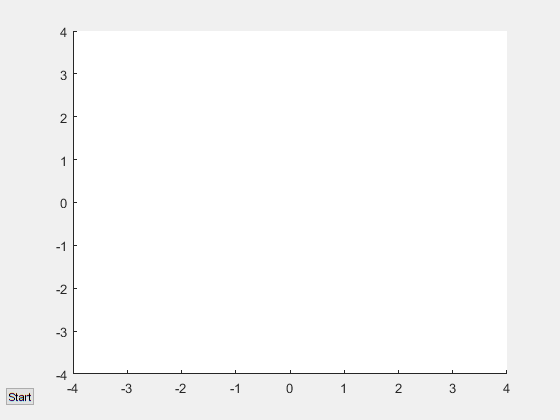

hb =   UIControl (Start) with properties:

              Style: 'pushbutton'
             String: 'Start'
    BackgroundColor: [0.9400 0.9400 0.9400]
           Callback: @startbuttonCallback
              Value: 0
           Position: [1 1 6 1.5000]
              Units: 'characters'

  Show all properties


% fh.UserData = true;
% fh.WindowButtonDownFcn = @(hObject, event) set(hjObject, 'UswerData', false);
% clf
axis([-4 4 -4 4])

hb = uicontrol('Style', 'pushbutton', 'Units', 'char', 'Position', [1 1 6 1.5],...
    'UserData', false, 'String', 'Start', 'Callback', @startbuttonCallback)

function startbuttonCallback(hObject, ~) % Don't need the second argument
% A callback for the Start/Stop button.

if hObject.UserData
    % Animation is currently running. Setting UserData to false stops it.
    hObject.UserData = false;
else
    % Animation is not running, so we start it and change the button text to
    % 'Stop'.
    hObject.UserData = true;
    hObject.String = 'Stop';
    
    cla % Clear the axes
    
    % Create an animatedline object with initial point (4, 1.9) and
    % set h to a handle to it.
    xo = 0; yo = 0;alpha = 0.1
    h = animatedline(xo, yo, 'LineStyle', 'none', 'Marker', 'o',...
        'MarkerSize', 5, 'MaximumNumPoints', Inf, 'Color', 'r');
    hx = uicontrol('Style', 'text', 'Units', 'char', 'Position', [10 1 5 1])
    hy = uicontrol('Style', 'text', 'Units', 'char', 'Position', [20 1 5 1])
    % The animation loop continues until UserData becomes false when the user
    % clicks the button.
    % We add new points to the plot with the function addpoints.
    ha =gca;
    dx = -0.5; dy = -0.5
    while hObject.UserData
        theta = rand(1)*2*pi;
        x = xo + alpha * cos(theta);
        y = yo + alpha * sin(theta);
        if x < ha.XLim(1)
            ha.XLim(1) = ha.XLim(1) + dx
        elseif x > ha.XLim(2)
            ha.XLim(2) = ha.XLim(2) - dx
        end
        if y < ha.YLim(1)
            ha.YLim(1) = ha.YLim(1) + dy
        elseif y > ha.YLim(2)
            ha.YLim(2) = ha.YLim(2) - dy
        end
        addpoints(h, x, y);
        drawnow
        xo = x; yo = y;
        hx.String = num2str(x);
        hy.String = num2str(y);
    end
    hObject.String = 'Start'; % Restore the button text to 'Start'
end
end
